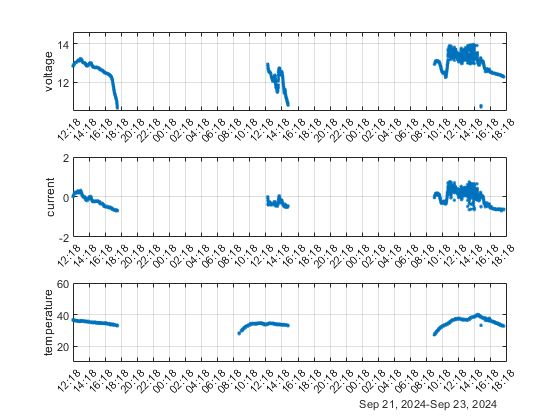

clear all
close all
% 假設檔案在同一個資料夾內
fileList = dir('*.txt'); % 選取當前資料夾下的所有 txt 檔案
data = []; % 用來儲存所有檔案的數據
time = []; % 用來儲存時間的數據
filen = length(fileList);

for j = 1:filen
    % 讀取每個檔案
    filename = fileList(j).name;
    fileID = fopen(filename, 'r');
    
    % 讀取檔案內容，並忽略空行
    fileData = textscan(fileID, '%s %f %f %f %f %f %f %f %f %f %f', 'Delimiter', '\t');
    
    % 關閉檔案
    fclose(fileID);
    
    % 提取檔名中的日期
    dateStr = extractBetween(filename, 'logger_', '_'); % 提取日期部分
    date = datetime(char(dateStr), 'InputFormat', 'yyyyMMdd'); % 根據檔名格式創建日期物件

    % 將日期與時間結合
    fullTime = strcat(repmat(string(date), length(fileData{1}), 1), '-', fileData{1}); % 將日期與時間字串結合
    fullTime = datetime(fullTime, 'InputFormat', 'dd-MMM-yyyy-HH:mm:ss.SS'); % 創建完整的日期時間物件
    time = [time; fullTime]; % 加入到時間陣列

    data = [data; fileData{2:end}]; % 跳過第一欄時間戳，加入其他數據
end

time = time(~isnat(time)); % 刪除 NaT 值
data(end,:)=[];
[n,~]=size(data);

acc = data(:, 1:3);
lat = data(:, 4);
lon = data(:, 5);
alt = data(:, 6);
gps = data(:, 7);
tem = data(:, 8);
v = data(:, 9);
i = data(:, 10);

for j=1:n
    if(i(j)==0)
        i(j)=NaN;
    end
end


figure(1);
subplot(3,1,1)
plot(time,v, '.');
ylabel('voltage')
ylim([10.5 14.6])
grid on;
xticks(time(1):hours(2):time(end)+0.1); % 設定 x 軸的刻度
datetick('x', 'HH:MM', 'keepticks'); % 格式化 x 軸標籤

subplot(3,1,2)
plot(time,i, '.');
ylabel('current')
ylim([-2 2])
grid on;
xticks(time(1):hours(2):time(end)+0.1);
datetick('x', 'HH:MM', 'keepticks');

subplot(3,1,3)
plot(time,tem, '.');
ylabel('temperature')
ylim([10 60])
grid on;
xticks(time(1):hours(2):time(end)+0.1);
datetick('x', 'HH:MM', 'keepticks');
xtickformat('HH:mm'); % 顯示時間

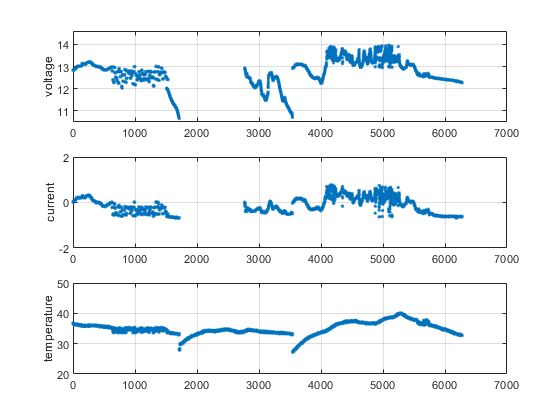



figure(2);
subplot(3,1,1)
plot(v, '.');
ylabel('voltage')
ylim([10.5 14.6])
grid on;
subplot(3,1,2)
plot(i, '.');
ylabel('current')
ylim([-2 2])
grid on;
subplot(3,1,3)
plot(tem, '.');
ylabel('temperature')
ylim([20 50])
grid on;